stats = 157×1 struct array with fields:
    Area
    Centroid
    BoundingBox


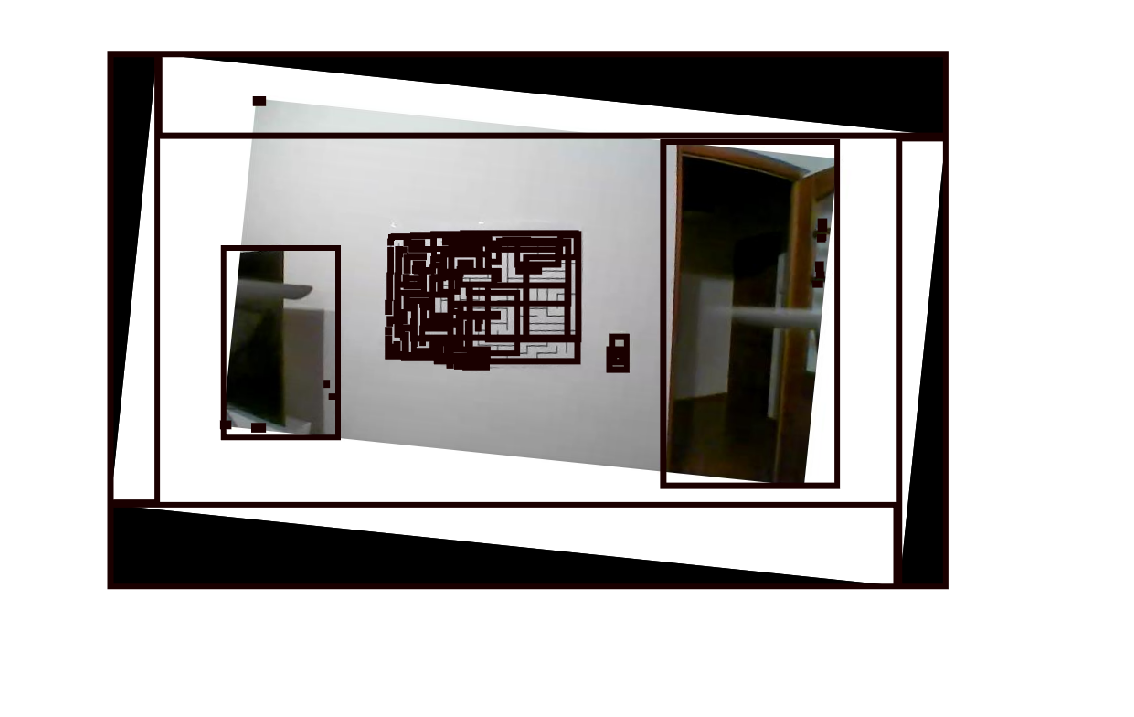

img = imread("pics\lab6.png");
image = findLabyrinth(img);

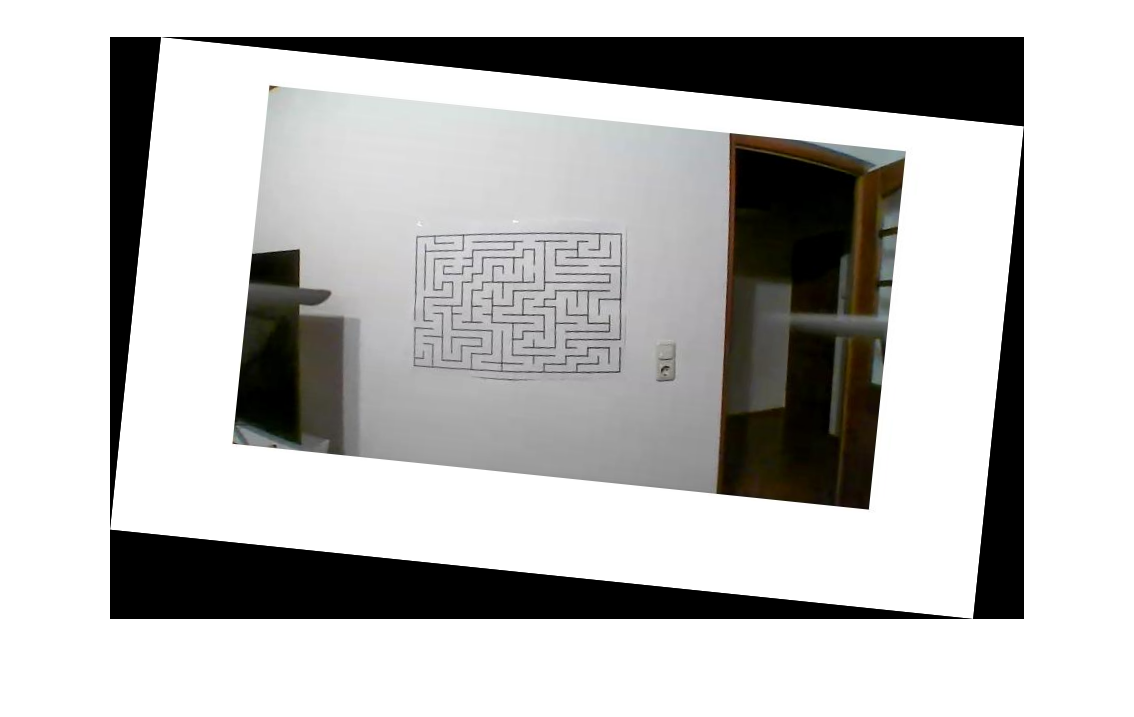

imshow(image);

p = parrot();

Unable to connect to a Parrot drone. Ensure that the drone is powered on and the computer is connected to the drone's WiFi network.

for iter = 1 : 10
    tic;
    test = "Hello" + iter;
    pause(1-toc);
end

count = 1;
snaps = {10};
while (count < 11)

    snaps{count} = imread(".\pics\labyrinth2.jpg");
    count = count + 1;
end


img = imread("pics\lab6.png");
nnet = googlenet;

resizedPicture = imresize(img,[224,224]);  % Resize the picture
label = classify(nnet,resizedPicture);         % Classify the picture
 title(char(label));

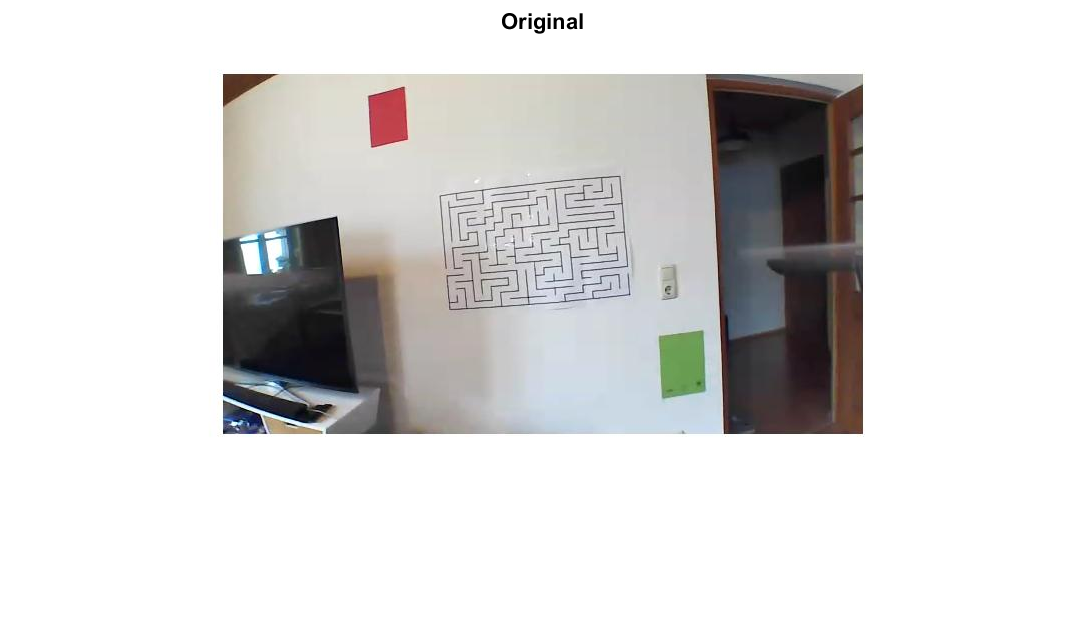

img = imread("pics\lab17.jpg");
%img = snapshots{3};
imshow(img);
title("Original");

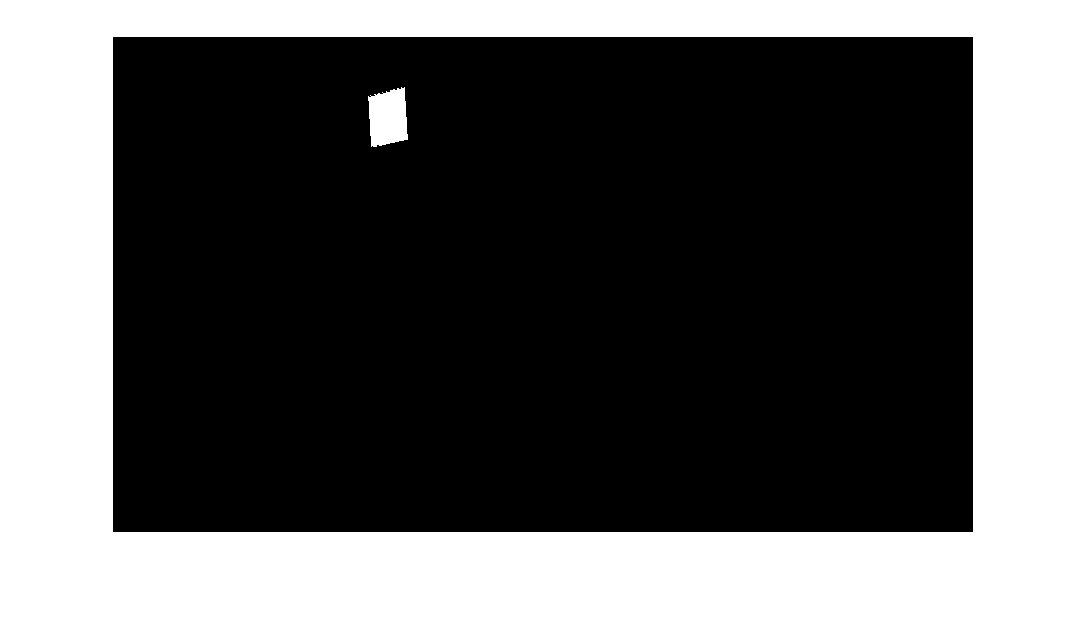


%final = imrotate(cutEndingPoint,-5,'bilinear','crop');
%imshow(final);
%title("Rotated");


cutStartingPoint = findStartingPointOfImage(img);

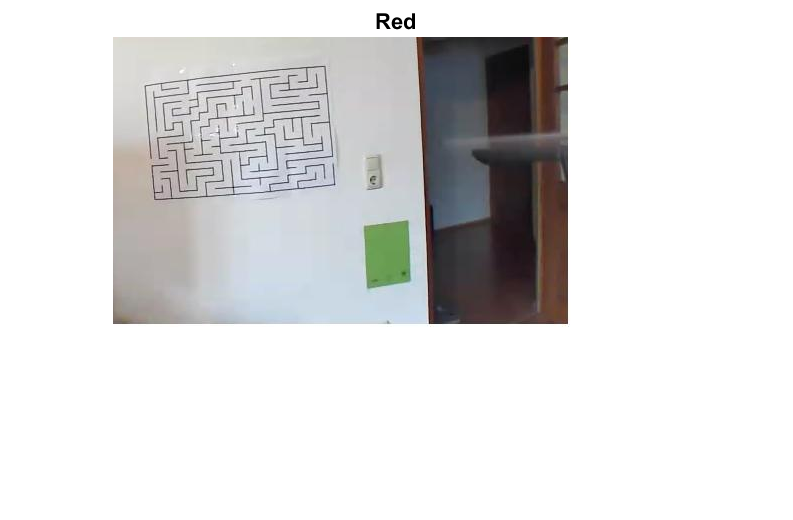

imshow(cutStartingPoint);
title("Red");

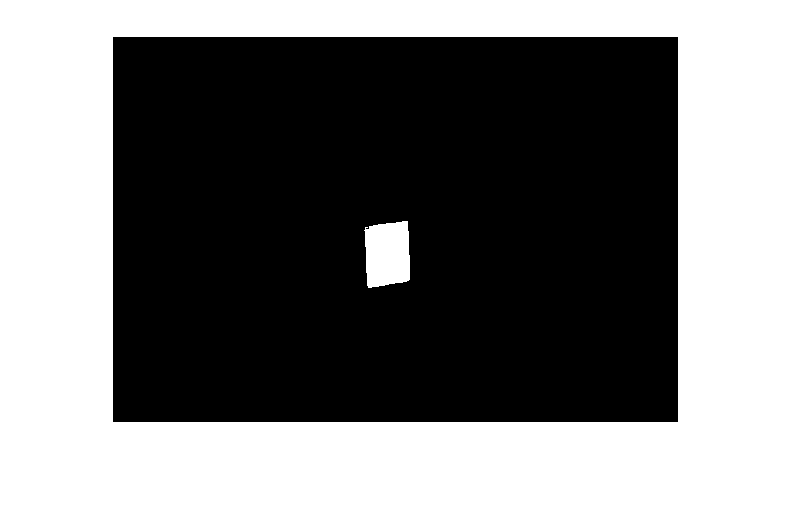


cutEndingPoint = findEndingPointOfImage(cutStartingPoint);

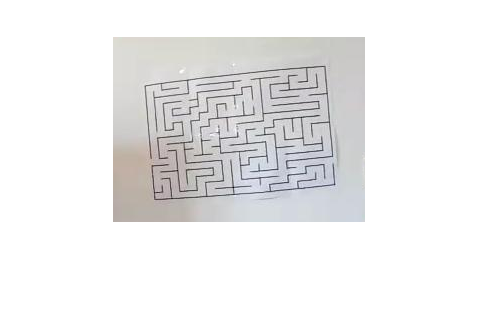

imshow(cutEndingPoint);

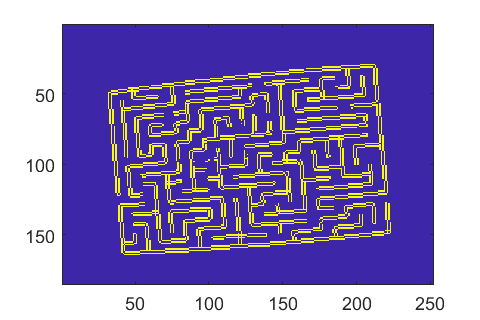





bild = rgb2gray(cutEndingPoint);
edges = edge(bild, 'Sobel', 0.1);
kantenFilter = imagesc(edges);

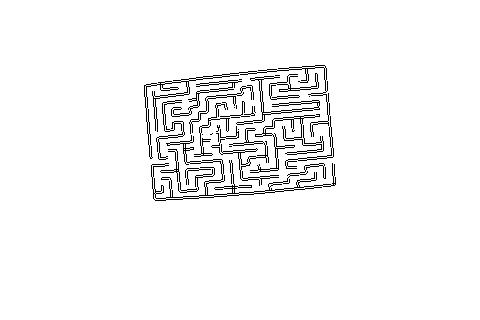

imshow(not(edges));

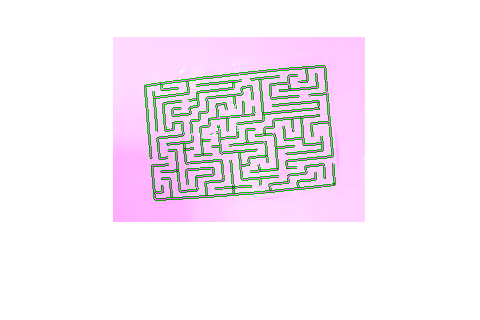

showpairImg = imshowpair(bild,not(edges));

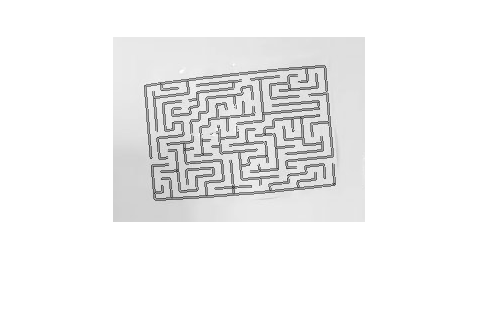



grayImage = rgb2gray(imfuse(bild, not(edges)) );
imshow(grayImage);

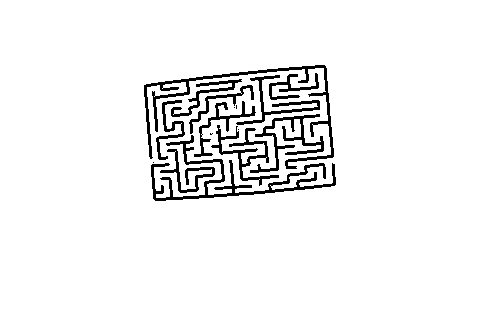


binaryImage = not(grayImage <= 200);
imshow((binaryImage));


%rotatedImg = rotateImage(binaryImage);
%imshow((rotatedImg));
%title("Rotated");
%mask = rotatedImg(:,:,1) > 180;

% Fill holes, and take the largest blob.
%binaryImage = imRotateWhite(binaryImage,-90);

sendImageToShortestPathFinder(binaryImage);
%findLabyrinth(cutEndingPoint);


function rotatedImage = rotateImage(maze)
%# detect corners in both
p1 = corner(maze, 'QualityLevel',0.5);

%# sort corners coordinates in a consistent way (counter-clockwise)
p1 = sortrows(p1,[2 1]);
idx = convhull(p1(:,1), p1(:,2));
p1 = p1(idx(1:end-1),:);

%# sort corners coordinates in a consistent way (counter-clockwise)
p1 = sort(p1);
topLeftMaze = p1(1,:);
topRightMaze = p1((end/2)-1,:);

slope = (topRightMaze(2) - topLeftMaze(2)) ./ (topRightMaze(1) - topLeftMaze(1));
degree = atand(slope);
rotatedImage = imRotateWhite(maze,-degree);
end

function largestRect = findLabyrinth(img)
bw = im2bw(img);
% find both black and white regions
stats = [regionprops(bw); regionprops(not(bw))];
% show the image and draw the detected rectangles on it
hold on;
imshow(img);
largestRectangle = stats(1).BoundingBox; 
for i = 1:numel(stats)
      rectangle('Position',stats(i).BoundingBox, 'Linewidth', 3, 'EdgeColor', [0.1 0 0]);
    if (stats(i).BoundingBox(4) > largestRectangle(4) )
        largestRectangle = stats(i).BoundingBox; 
      
    end
end

largestRect = imcrop(img,largestRectangle);
end